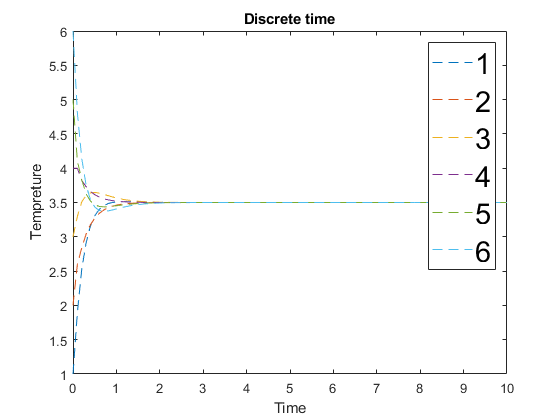

clear all;
close all;
clc;

n = 6;
T_ini = [1  2   3   4   5   6]';


tspan = linspace(0,10,100);
iter = length(tspan);
T = zeros(n, iter);
T(:,1) = T_ini;
%========================%
%descritization using the sensing matrix
%P = [0.5 0.5 0;0 0.5 0.5;0.5 0 0.5]
%normal descritization 
eps=0.3;
%eps=0.9;
L=[2,-1,-1,0,0,0;
-1,2,0,0,-1,0;
0,0,1,-1,0,0;
0,0,-1,2,-1,0;
0,-1,0,-1,3,-1;
0,-1,0,0,0,1];

P=eye(6)-eps*L;

for k = 1 : iter-1
    
    T(:,k+1) = P * T(:,k);

end
    
figure(1)
plot(tspan,T,'--');
xlabel('Time');
ylabel('Tempreture')
legend('1','2','3','4','5','6', 'FontSize', 22)
title('Discrete time')

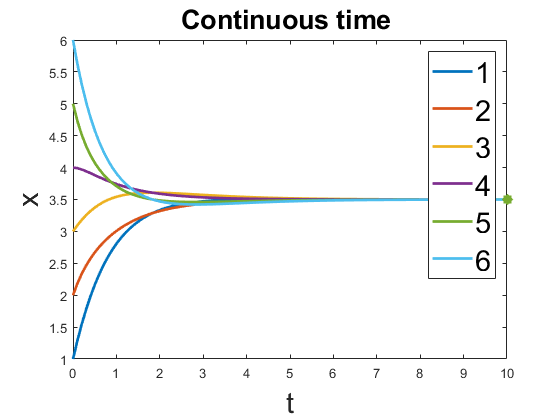

%continuous time


options = odeset('RelTol',1e-5);
[t, x] = ode45(@ode, tspan, T_ini , options);


figure(2)
n1 = length(x);
x = x(1:n1,:);
plot(t,x,'linewidth',2)
hold on
plot(t(end,:),x(end,:),'*','linewidth',6);

xlabel('t', 'FontSize', 22);
ylabel('x', 'FontSize', 22);
legend('1','2','3','4','5','6', 'FontSize', 22)
title('Continuous time ', 'FontSize', 20)

function x_dot = ode(t, x)
L=[2,-1,-1,0,0,0;
-1,2,0,0,-1,0;
0,0,1,-1,0,0;
0,0,-1,2,-1,0;
0,-1,0,-1,3,-1;
0,-1,0,0,0,1];
x_dot = -L * x;

end